close all
clear variables

# Калтбровка

calibzero0 = load('calibzero.dat')

calibzero0 =     1.0000  483.9500
    2.0000  483.2750
    3.0000  483.5500
    4.0000  483.5000
    5.0000  483.2500
    6.0000  482.8250
    7.0000  481.2750
    8.0000  484.5750
    9.0000  483.5500
   10.0000  483.7000


calib0 = load('calib.dat')

calib0 = 	1.0e+03 *

    0.0010    1.0314
    0.0020    1.0358
    0.0030    1.0357
    0.0040    1.0305
    0.0050    1.0365
    0.0060    1.0355
    0.0070    1.0337
    0.0080    1.0284
    0.0090    1.0341
    0.0100    1.0307



calibzero = (calibzero0(:,2))'

calibzero =   483.9500  483.2750  483.5500  483.5000  483.2500  482.8250  481.2750  484.5750  483.5500  483.7000  481.4250  483.0250  482.6750  482.0500  482.6250  481.8000  481.4000  481.7250  482.3500  481.3000  480.4750  481.3500  480.8500  483.6500  483.7000  483.3000  483.1500  481.0000  482.9750  480.7500  483.1750  483.3500  481.8500  482.3000  484.6000  484.6500  482.9000  484.2500  481.7750  482.4000  481.5250  482.3500  481.6250  482.6500  482.3250  483.5500  483.8250  482.1000  481.9500  482.5500


calib = (calib0(:,2))'

calib = 	1.0e+03 *

    1.0314    1.0358    1.0357    1.0305    1.0365    1.0355    1.0337    1.0284    1.0341    1.0307    1.0270    1.0301    1.0366    1.0331    1.0286    1.0323    1.0346    1.0356    1.0317    1.0350    1.0354    1.0381    1.0363    1.0314    1.0357    1.0300    1.0340    1.0400    1.0371    1.0329    1.0356    1.0333    1.0391    1.0300    1.0316    1.0348    1.0333    1.0383    1.0288    1.0433    1.0385    1.0366    1.0340    1.0337    1.0392    1.0356    1.0328    1.0342    1.0348    1.0321



x = [calibzero calib]

x = 	1.0e+03 *

    0.4839    0.4833    0.4836    0.4835    0.4833    0.4828    0.4813    0.4846    0.4836    0.4837    0.4814    0.4830    0.4827    0.4821    0.4826    0.4818    0.4814    0.4817    0.4824    0.4813    0.4805    0.4814    0.4808    0.4836    0.4837    0.4833    0.4831    0.4810    0.4830    0.4808    0.4832    0.4834    0.4819    0.4823    0.4846    0.4846    0.4829    0.4843    0.4818    0.4824    0.4815    0.4824    0.4816    0.4826    0.4823    0.4836    0.4838    0.4821    0.4819    0.4826



manometer = ones(size(calib)).*67.1

manometer =    67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000   67.1000


null = zeros(size(calibzero))

null =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



y = [null manometer]

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



p = polyfit(x, y, 1)

p =     0.1216  -58.7485



f1 = figure

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


figure(f1)
plot(calibzero, null, 'bo', 'MarkerFaceColor','b')
hold on
grid on
plot(calib, manometer, 'ro', 'MarkerFaceColor','r')

x1 = [min(calibzero) max(calib)]

x1 = 	1.0e+03 *

    0.4798    1.0433


y1 = [polyval(p, x1(1)) polyval(p, x1(2))]

y1 =    -0.3879   68.1704



plot(x1, y1)

title('Калибровка')
xlabel('Отсчеты АЦП')
ylabel('\DeltaP, Па')

str = ['\DeltaP (adc) = ' num2str(p(1)) '*adc + ' num2str(p(2))]

str = '\DeltaP (adc) = 0.12165*adc + -58.7485'

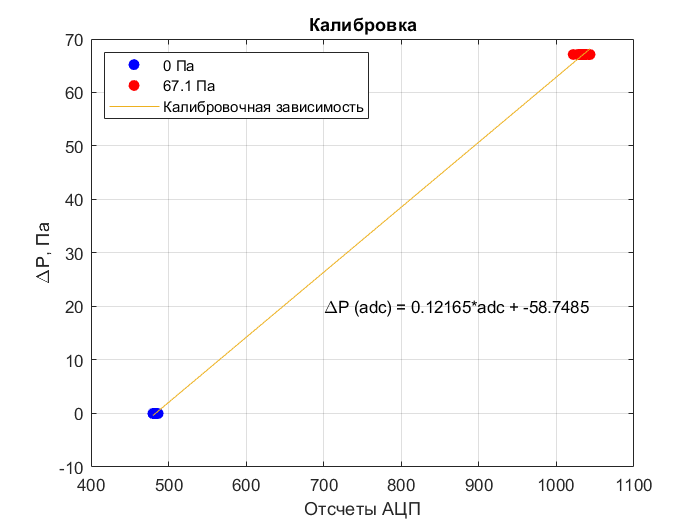

text(700, 20, str)
legend('0 Па', '67.1 Па', 'Калибровочная зависимость', 'Location','northwest')

saveas(f1, 'Калибровка.png')


mm01 = load("01mm.dat")

mm01 = 	1.0e+03 *

    0.0010    0.4824
    0.0020    0.4788
    0.0030    0.4799
    0.0040    0.4791
    0.0050    0.4824
    0.0060    0.4822
    0.0070    0.4835
    0.0080    0.4796
    0.0090    0.4809
    0.0100    0.4794


mm11 = load("11mm.dat")

mm11 = 	1.0e+03 *

    0.0010    0.4829
    0.0020    0.4807
    0.0030    0.4870
    0.0040    0.4804
    0.0050    0.4801
    0.0060    0.4866
    0.0070    0.4835
    0.0080    0.4814
    0.0090    0.4802
    0.0100    0.4856


mm21 = load("21mm.dat")

mm21 = 	1.0e+03 *

    0.0010    0.4824
    0.0020    0.4821
    0.0030    0.4804
    0.0040    0.4791
    0.0050    0.4805
    0.0060    0.4830
    0.0070    0.4804
    0.0080    0.4778
    0.0090    0.4765
    0.0100    0.4798


mm31 = load("31mm.dat")

mm31 = 	1.0e+03 *

    0.0010    0.4826
    0.0020    0.4774
    0.0030    0.4797
    0.0040    0.4792
    0.0050    0.4799
    0.0060    0.4761
    0.0070    0.4769
    0.0080    0.4785
    0.0090    0.4959
    0.0100    0.4903


mm41 = load("41mm.dat")

mm41 = 	1.0e+03 *

    0.0010    0.4865
    0.0020    0.5092
    0.0030    0.4818
    0.0040    0.4933
    0.0050    0.5240
    0.0060    0.4963
    0.0070    0.5257
    0.0080    0.5126
    0.0090    0.5152
    0.0100    0.5948


mm51 = load("51mm.dat")

mm51 = 	1.0e+03 *

    0.0010    0.4937
    0.0020    0.4979
    0.0030    0.5045
    0.0040    0.5066
    0.0050    0.5245
    0.0060    0.4957
    0.0070    0.5159
    0.0080    0.5484
    0.0090    0.5658
    0.0100    0.5733


mm61 = load("61mm.dat")

mm61 = 	1.0e+03 *

    0.0010    0.5300
    0.0020    0.5424
    0.0030    0.5843
    0.0040    0.5341
    0.0050    0.5456
    0.0060    0.5681
    0.0070    0.5376
    0.0080    0.5534
    0.0090    0.6041
    0.0100    0.6466


mm71 = load("71mm.dat")

mm71 = 	1.0e+03 *

    0.0010    0.5781
    0.0020    0.5308
    0.0030    0.5659
    0.0040    0.6069
    0.0050    0.5856
    0.0060    0.7008
    0.0070    0.6202
    0.0080    0.6416
    0.0090    0.6556
    0.0100    0.6637



dx = 0.25;
x = mm01(:,1)'.*dx

x =     0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500   12.5000



p01 = polyval(p, mm01(:, 2)')

p01 =    -0.0655   -0.5096   -0.3697   -0.4731   -0.0655   -0.0899    0.0683   -0.4001   -0.2419   -0.4244   -0.0473    0.1048    0.3846   -0.0108   -0.0716    0.0865   -0.4122   -0.3575    0.0987   -0.1750    0.2082    0.1352    0.1413    0.2507   -0.0047    0.3906    0.0135    0.2507   -0.0108    0.4332    0.3481    0.0500    1.4368   45.5402  233.0056  375.0173  409.1517  413.8777  421.8518  421.7849  418.7558  419.6682  420.7387  418.8896  421.4442  419.3458  422.8128  417.3751  419.9054  423.4028


p11 = polyval(p, mm11(:, 2)')

p11 =    -0.0047   -0.2723    0.4940   -0.3088   -0.3453    0.4454    0.0683   -0.1872   -0.3332    0.3237    0.3481    0.2751    0.1778   -0.1142   -0.0290   -0.6130   -0.2602   -0.3453   -0.1264   -0.0412    0.1534   -0.1872   -0.2723   -0.0899    0.3724   -0.5521   -0.4791   -0.3453   -0.8319   -0.8927   -0.4913   -0.6859   -1.1117   -0.5643   -0.6373    3.4987    8.9607   33.2538   68.3492  136.2895  210.5190  301.2805  362.2504  395.9347  415.9214  415.9458  424.5463  419.3641  425.5194  420.5927


p21 = polyval(p, mm21(:, 2)')

p21 =    -0.0655   -0.1020   -0.3088   -0.4670   -0.2967    0.0074   -0.3088   -0.6251   -0.7833   -0.3818    0.3116   -0.1385   -0.5765   -0.5278   -0.2480   -0.4183   -0.5278   -0.4062   -0.1264    2.9757    3.0121    2.0876    6.2966    8.7418    9.4960   14.0578   20.5294   26.5145   45.6132   75.7819  105.0139  140.2188  187.0532  224.4112  276.1967  292.2056  338.6142  362.6762  379.0135  402.9051  403.1727  420.3981  423.5244  424.0110  424.8625  423.3419  421.6024  418.4030  422.1741  420.4832


p31 = polyval(p, mm31(:, 2)')

p31 =    -0.0412   -0.6738   -0.3940   -0.4548   -0.3697   -0.8319   -0.7346   -0.5400    1.5767    0.8955    0.7860    2.3674    3.8394    1.1144    4.3138    9.0094   14.4106   11.9411   14.4592   25.4562   34.4703   32.5118   35.9909   44.6279   43.4722   65.4053   87.8615   97.8610  142.9802  138.3697  168.8060  197.5514  217.3435  261.8301  292.6192  307.3629  332.1669  352.5307  365.0848  378.0768  386.4218  399.5355  403.9148  414.6685  406.3842  412.5031  415.2402  415.3740  418.3422  414.1697


p41 = polyval(p, mm41(:, 2)')

p41 =     0.4332    3.1946   -0.1385    1.2604    4.9950    1.6254    5.2018    3.6082    3.9245   13.6077    7.8902   14.1429   10.3840   15.8947   19.4833   28.2784   21.2837   31.0885   26.6727   35.1393   53.9704   53.6541   60.5516   77.3876   75.2466   88.6887  113.2251  118.8817  144.9387  159.8041  173.8544  206.7966  226.4549  243.3761  264.1171  272.3405  309.8567  306.9858  331.5465  350.8155  351.9955  366.9947  374.5125  374.1841  385.7649  390.6430  384.3660  388.1614  377.6510  378.5999


p51 = polyval(p, mm51(:, 2)')

p51 =     1.3091    1.8200    2.6229    2.8783    5.0558    1.5524    4.0097    7.9632   10.0799   10.9922    9.7271   14.3254   17.6342   19.2521   25.7481   37.5845   40.2850   32.5482   35.5894   41.9516   49.8952   61.5856   71.3296   77.3390   82.1076   96.2674  102.9094  113.8455  130.5113  132.1048  137.6641  157.5414  180.3504  175.8372  204.7894  216.8204  218.7911  266.9271  271.7201  282.9847  268.1801  308.2509  307.8616  296.2321  316.5108  326.4738  328.7486  325.6587  334.0038  323.3353


p61 = polyval(p, mm61(:, 2)')

p61 =     5.7249    7.2333   12.3304    6.2237    7.6226   10.3597    6.6494    8.5715   14.7390   19.9090   20.4321   29.0083   30.2369   26.3077   27.5850   42.2557   44.7009   45.3334   57.7050   52.6445   65.2594   85.6110   84.5892   83.8471   91.1582  108.8944  108.4443  118.2370  132.2873  140.4864  134.2823  160.6678  168.9155  187.1627  180.7518  189.7416  203.5851  203.8162  216.3703  224.1193  226.7347  248.9111  253.3391  251.9280  258.6064  263.2291  274.6031  275.6980  255.1151  262.6451


p71 = polyval(p, mm71(:, 2)')

p71 =    11.5762    5.8222   10.0921   15.0796   12.4885   26.5023   16.6975   19.3008   21.0039   21.9892   27.8161   32.0617   26.0766   43.5209   44.9320   40.8325   63.4346   55.5883   77.0349   67.3639   65.3932   77.3390   79.7111   87.5331  100.0750  111.5342  105.1477  108.5538  134.1607  122.7258  144.8900  140.3647  156.2519  163.6116  154.6219  166.5312  189.4496  186.5666  195.3374  193.7073  197.5514  192.9166  196.4444  190.8851  211.4192  204.5948  220.5793  215.5309  207.8914  199.6802



pressure = [p01; p11; p21; p31; p41; p51; p61; p71]

pressure =    -0.0655   -0.5096   -0.3697   -0.4731   -0.0655   -0.0899    0.0683   -0.4001   -0.2419   -0.4244   -0.0473    0.1048    0.3846   -0.0108   -0.0716    0.0865   -0.4122   -0.3575    0.0987   -0.1750    0.2082    0.1352    0.1413    0.2507   -0.0047    0.3906    0.0135    0.2507   -0.0108    0.4332    0.3481    0.0500    1.4368   45.5402  233.0056  375.0173  409.1517  413.8777  421.8518  421.7849  418.7558  419.6682  420.7387  418.8896  421.4442  419.3458  422.8128  417.3751  419.9054  423.4028
   -0.0047   -0.2723    0.4940   -0.3088   -0.3453    0.4454    0.0683   -0.1872   -0.3332    0.3237    0.3481    0.2751    0.1778   -0.1142   -0.0290   -0.6130   -0.2602   -0.3453   -0.1264   -0.0412    0.1534   -0.1872   -0.2723   -0.0899    0.3724   -0.5521   -0.4791   -0.3453   -0.8319   -0.8927   -0.4913   -0.6859   -1.1117   -0.5643   -0.6373    3.4987    8.9607   33.2538   68.3492  136.2895  210.5190  301.2805  362.2504  395.9347  415.9214  415.9458  424.5463  419.3641  425.51

Names = {'1 мм', '11 мм', '21 мм', '31 мм', '41 мм', '51 мм', '61 мм', '71 мм'}

Names = 1×8 cell array
    {'1 мм'}    {'11 мм'}    {'21 мм'}    {'31 мм'}    {'41 мм'}    {'51 мм'}    {'61 мм'}    {'71 мм'}



f2 = figure

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


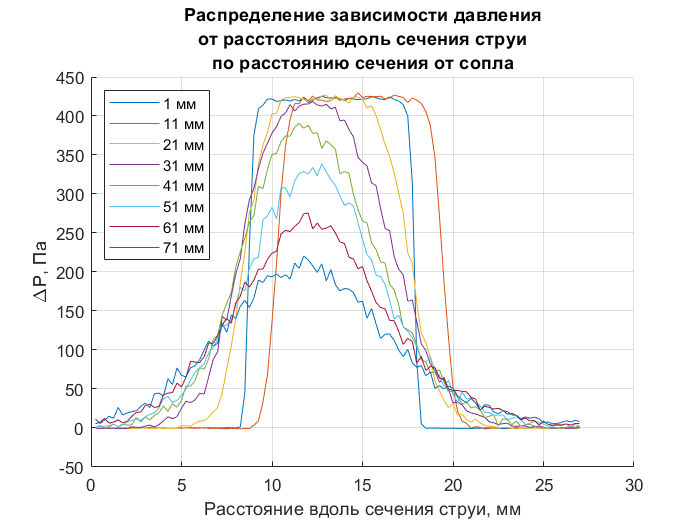

figure(f2)
hold on
grid on
title({'Распределение зависимости давления', 'от расстояния вдоль сечения струи', 'по расстоянию сечения от сопла'})
ylabel('\DeltaP, Па')
xlabel('Расстояние вдоль сечения струи, мм')

for i = 1:size(pressure, 1)
    plot(x, pressure(i,:),'DisplayName', Names{i})
end

legend('Location',"northwest")

saveas(f2, 'Давление.png')



f3 = figure

f3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


figure(f3)
hold on
grid on
title('Центровка')
ylabel('\DeltaP, Па')
xlabel({'Расстояние вдоль сечения струи','относительно ее центра, мм'})

xCentered = zeros(size(pressure))

xCentered =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

offset = 50

offset = 50


for i = 1:size(pressure,1)
    max = x(find(pressure(i,:) > offset, 1, "last"))
    min = x(find(pressure(i,:) > offset, 1, 'first'))
    center = min + (max - min)/2
    xCentered(i,:) = x - center
    plot(xCentered(i,:), pressure(i,:), 'DisplayName', Names{i})
end

max = 18

min = 8.7500

center = 13.3750

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

max = 20

min = 9.7500

center = 14.8750

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 19

min = 7.5000

center = 13.2500

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 19.7500

min = 6.5000

center = 13.1250

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 19.5000

min = 5.2500

center = 12.3750

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 19.7500

min = 5.5000

center = 12.6250

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 19.5000

min = 4.7500

center = 12.1250

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

max = 20

min = 4.2500

center = 12.1250

xCentered =   -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6250   -2.3750   -2.1250   -1.8750   -1.6250   -1.3750   -1.1250   -0.8750
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750   -7.1250   -6.8750   -6.6250   -6.3750   -6.1250   -5.8750   -5.6250   -5.3750   -5.1250   -4.8750   -4.6250   -4.3750   -4.1250   -3.8750   -3.6250   -3.3750   -3.1250   -2.8750   -2.6

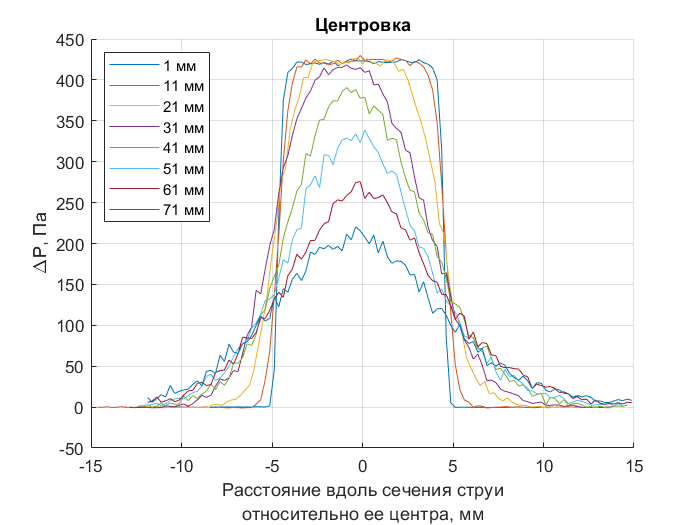


legend('Location',"northwest")

saveas(f3, 'Центр.png')


ro = 1.2

ro = 1.2000

sum = 0

sum = 0

for i = 1:length(calibzero)
    sum = sum + calibzero(i)
end

sum = 483.9500

sum = 967.2250

sum = 1.4508e+03

sum = 1.9343e+03

sum = 2.4175e+03

sum = 2.9003e+03

sum = 3.3816e+03

sum = 3.8662e+03

sum = 4.3497e+03

sum = 4.8334e+03

sum = 5.3149e+03

sum = 5.7979e+03

sum = 6.2806e+03

sum = 6.7626e+03

sum = 7.2452e+03

sum = 7.7270e+03

sum = 8.2084e+03

sum = 8.6902e+03

sum = 9.1725e+03

sum = 9.6538e+03

sum = 1.0134e+04

sum = 1.0616e+04

sum = 1.1097e+04

sum = 1.1580e+04

sum = 1.2064e+04

sum = 1.2547e+04

sum = 1.3030e+04

sum = 1.3511e+04

sum = 1.3994e+04

sum = 1.4475e+04

sum = 1.4958e+04

sum = 1.5442e+04

sum = 1.5923e+04

sum = 1.6406e+04

sum = 1.6890e+04

sum = 1.7375e+04

sum = 1.7858e+04

sum = 1.8342e+04

sum = 1.8824e+04

sum = 1.9306e+04

sum = 1.9788e+04

sum = 2.0270e+04

sum = 2.0752e+04

sum = 2.1234e+04

sum = 2.1717e+04

sum = 2.2200e+04

sum = 2.2684e+04

sum = 2.3166e+04

sum = 2.3648e+04

sum = 2.4131e+04

sum = 2.4614e+04

sum = 2.5097e+04

sum = 2.5580e+04

sum = 2.6063e+04

sum = 2.6546e+04

sum = 2.7029e+04

sum = 2.7509e+04

sum = 2.7989e+04

sum = 2.8475e+04

sum = 2.8961e+04

sum = 2.9447e+04

sum = 2.9932e+04

sum = 3.0418e+04

sum = 3.0902e+04

sum = 3.1385e+04

sum = 3.1871e+04

sum = 3.2355e+04

sum = 3.2838e+04

sum = 3.3320e+04

sum = 3.3802e+04

sum = 3.4285e+04

sum = 3.4768e+04

sum = 3.5252e+04

sum = 3.5738e+04

sum = 3.6225e+04

sum = 3.6708e+04

sum = 3.7191e+04

sum = 3.7674e+04

sum = 3.8156e+04

sum = 3.8638e+04

sum = 3.9123e+04

sum = 3.9607e+04

sum = 4.0092e+04

sum = 4.0575e+04

sum = 4.1060e+04

sum = 4.1544e+04

sum = 4.2028e+04

sum = 4.2510e+04

sum = 4.2993e+04

sum = 4.3474e+04

sum = 4.3957e+04

sum = 4.4441e+04

sum = 4.4923e+04

sum = 4.5406e+04

sum = 4.5890e+04

sum = 4.6372e+04

sum = 4.6852e+04

sum = 4.7333e+04

sum = 4.7815e+04

sum = 4.8297e+04

sum = sum/length(calibzero)

sum = 482.9668

Pst = polyval(p, sum)

Pst = 0.0034

P0 = polyval(p, calib)

P0 =    66.7252   67.2580   67.2446   66.6060   67.3456   67.2179   66.9989   66.3517   67.0512   66.6279   66.1875   66.5646   67.3493   66.9296   66.3822   66.8347   67.1060   67.2337   66.7532   67.1571   67.2033   67.5342   67.3188   66.7252   67.2398   66.5427   67.0391   67.7616   67.4101   66.8992   67.2337   66.9503   67.6534   66.5549   66.7410   67.1364   66.9478   67.5585   66.4028   68.1704   67.5889   67.3493   67.0391   66.9928   67.6655   67.2337   66.8931   67.0537   67.1327   66.8018



v01 = sqrt(2*abs(p01 - Pst)/ro)

v01 =     0.3390    0.9246    0.7885    0.8911    0.3390    0.3943    0.3288    0.8200    0.6394    0.8444    0.2907    0.4110    0.7970    0.1539    0.3536    0.3722    0.8323    0.7756    0.3985    0.5453    0.5842    0.4686    0.4793    0.6421    0.1163    0.8034    0.1299    0.6421    0.1539    0.8464    0.7579    0.2788    1.5456    8.7118   19.7063   25.0005   26.1135   26.2639   26.5157   26.5136   26.4182   26.4470   26.4807   26.4224   26.5029   26.4368   26.5459   26.3746   26.4544   26.5644


v11 = sqrt(2*abs(p11 - Pst)/ro)

v11 =     0.1163    0.6779    0.9043    0.7214    0.7624    0.8583    0.3288    0.5636    0.7490    0.7307    0.7579    0.6729    0.5391    0.4427    0.2326    1.0135    0.6628    0.7624    0.4651    0.2727    0.5000    0.5636    0.6779    0.3943    0.7842    0.9622    0.8968    0.7624    1.1799    1.2221    0.9080    1.0719    1.3633    0.9727    1.0334    2.4136    3.8638    7.4443   10.6728   15.0713   18.7312   22.4082   24.5712   25.6882   26.3286   26.3294   26.6002   26.4374   26.6307   26.4761


v21 = sqrt(2*abs(p21 - Pst)/ro)

v21 =     0.3390    0.4192    0.7214    0.8854    0.7072    0.0821    0.7214    1.0235    1.1450    0.8013    0.7167    0.4864    0.9831    0.9409    0.6473    0.8384    0.9409    0.8262    0.4651    2.2257    2.2393    1.8638    3.2386    3.8163    3.9776    4.8398    5.8489    6.6472    8.7187   11.2382   13.2294   15.2870   17.6564   19.3394   21.4551   22.0682   23.7561   24.5857   25.1333   25.9134   25.9220   26.4699   26.5682   26.5834   26.6101   26.5625   26.5078   26.4071   26.5258   26.4726


v31 = sqrt(2*abs(p31 - Pst)/ro)

v31 =     0.2727    1.0624    0.8138    0.8739    0.7885    1.1799    1.1091    0.9516    1.6193    1.2193    1.1421    1.9849    2.5285    1.3608    2.6803    3.8743    4.9002    4.4605    4.9085    6.5132    7.5792    7.3607    7.7446    8.6240    8.5116   10.4405   12.1008   12.7709   15.4368   15.1859   16.7731   18.1452   19.0324   20.8897   22.0838   22.6333   23.5288   24.2393   24.6672   25.1022   25.3778   25.8048   25.9458   26.2889   26.0250   26.2202   26.3071   26.3113   26.4051   26.2731


v41 = sqrt(2*abs(p41 - Pst)/ro)

v41 =     0.8464    2.3062    0.4864    1.4474    2.8843    1.6442    2.9435    2.4511    2.5564    4.7617    3.6256    4.8545    4.1594    5.1464    5.6979    6.8648    5.9554    7.1978    6.6670    7.6524    9.4839    9.4561   10.0456   11.3567   11.1985   12.1577   13.7369   14.0759   15.5422   16.3198   17.0221   18.5649   19.4273   20.1400   20.9807   21.3048   22.7249   22.6194   23.5068   24.1803   24.2209   24.7316   24.9836   24.9727   25.3562   25.5160   25.3102   25.4348   25.0881   25.1196


v51 = sqrt(2*abs(p51 - Pst)/ro)

v51 =     1.4752    1.7400    2.0894    2.1890    2.9018    1.6067    2.5840    3.6423    4.0981    4.2796    4.0257    4.8857    5.4208    5.6640    6.5504    7.9142    8.1937    7.3649    7.7013    8.3614    9.1188   10.1310   10.9031   11.3531   11.6979   12.6665   13.0962   13.7745   14.7483   14.8381   15.1471   16.2038   17.3372   17.1189   18.4746   19.0095   19.0957   21.0920   21.2805   21.7172   21.1415   22.6660   22.6516   22.2197   22.9676   23.3263   23.4074   23.2972   23.5938   23.2139


v61 = sqrt(2*abs(p61 - Pst)/ro)

v61 =     3.0880    3.4713    4.5327    3.2198    3.5635    4.1546    3.3282    3.7789    4.9557    5.7599    5.8351    6.9528    7.0985    6.6212    6.7801    8.3917    8.6311    8.6920    9.8066    9.3667   10.4288   11.9448   11.8733   11.8211   12.3258   13.4716   13.4438   14.0377   14.8483   15.3016   14.9599   16.3638   16.7786   17.6616   17.3565   17.7829   18.4202   18.4306   18.9898   19.3268   19.4393   20.3678   20.5481   20.4908   20.7607   20.9454   21.3931   21.4357   20.6200   20.9221


v71 = sqrt(2*abs(p71 - Pst)/ro)

v71 =     4.3918    3.1142    4.1005    5.0127    4.5616    6.6457    5.2748    5.6712    5.9161    6.0533    6.8084    7.3096    6.5921    8.5164    8.6534    8.2491   10.2820    9.6250   11.3307   10.5956   10.4395   11.3531   11.5259   12.0782   12.9146   13.6340   13.2378   13.4506   14.9531   14.3017   15.5396   15.2950   16.1374   16.5130   16.0530   16.6597   17.7692   17.6335   18.0432   17.9677   18.1452   17.9310   18.0942   17.8364   18.7712   18.4658   19.1736   18.9529   18.6140   18.2427



v = [v01; v11; v21; v31; v41; v51; v61; v71]

v =     0.3390    0.9246    0.7885    0.8911    0.3390    0.3943    0.3288    0.8200    0.6394    0.8444    0.2907    0.4110    0.7970    0.1539    0.3536    0.3722    0.8323    0.7756    0.3985    0.5453    0.5842    0.4686    0.4793    0.6421    0.1163    0.8034    0.1299    0.6421    0.1539    0.8464    0.7579    0.2788    1.5456    8.7118   19.7063   25.0005   26.1135   26.2639   26.5157   26.5136   26.4182   26.4470   26.4807   26.4224   26.5029   26.4368   26.5459   26.3746   26.4544   26.5644
    0.1163    0.6779    0.9043    0.7214    0.7624    0.8583    0.3288    0.5636    0.7490    0.7307    0.7579    0.6729    0.5391    0.4427    0.2326    1.0135    0.6628    0.7624    0.4651    0.2727    0.5000    0.5636    0.6779    0.3943    0.7842    0.9622    0.8968    0.7624    1.1799    1.2221    0.9080    1.0719    1.3633    0.9727    1.0334    2.4136    3.8638    7.4443   10.6728   15.0713   18.7312   22.4082   24.5712   25.6882   26.3286   26.3294   26.6002   26.4374   26.6307   26


xvCentered = zeros(size(v))

xvCentered =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

offset = 12

offset = 12


hold off


for i = 1:size(v,1)
    max = x(find(v(i,:) > offset, 1, "last"))
    min = x(find(v(i,:) > offset, 1, 'first'))
    center = min + (max - min)/2
    xvCentered(i,:) = x - center
end

max = 17.7500

min = 8.7500

center = 13.2500

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0        

max = 19.7500

min = 10

center = 14.8750

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0        

max = 18.7500

min = 7.7500

center = 13.2500

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
         0         0         0         0         0         0         0        

max = 18.5000

min = 6.7500

center = 12.6250

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.62

max = 18.2500

min = 6.5000

center = 12.3750

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.62

max = 18.7500

min = 6.5000

center = 12.6250

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.62

max = 18.2500

min = 6.2500

center = 12.2500

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.62

max = 17.5000

min = 6

center = 11.7500

xvCentered = 8×108
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -14.6250  -14.3750  -14.1250  -13.8750  -13.6250  -13.3750  -13.1250  -12.8750  -12.6250  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.6250  -10.3750  -10.1250   -9.8750   -9.6250   -9.3750   -9.1250   -8.8750   -8.6250   -8.3750   -8.1250   -7.8750   -7.6250   -7.3750
  -13.0000  -12.7500  -12.5000  -12.2500  -12.0000  -11.7500  -11.5000  -11.2500  -11.0000  -10.7500  -10.5000  -10.2500  -10.0000   -9.7500   -9.5000   -9.2500   -9.0000   -8.7500   -8.5000   -8.2500   -8.0000   -7.7500   -7.5000   -7.2500   -7.0000   -6.7500   -6.5000   -6.2500   -6.0000   -5.7500
  -12.3750  -12.1250  -11.8750  -11.6250  -11.3750  -11.1250  -10.8750  -10.62


f4 = figure

f4 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


figure(f4)

plot3(10,10,10)

hold on
grid on

z = ones(size(pressure))

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 


for i = 1:8
    z(i,:) = z(i,:)*((i - 1)*10 + 1)
end

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31
    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41
     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31
    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41
    51    51    51    51    51    51    51    51    51    51    51    51    51    51 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31
    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41
    51    51    51    51    51    51    51    51    51    51    51    51    51    51 

z = 8×108
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11    11
    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21    21
    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31    31
    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41
    51    51    51    51    51    51    51    51    51    51    51    51    51    51 

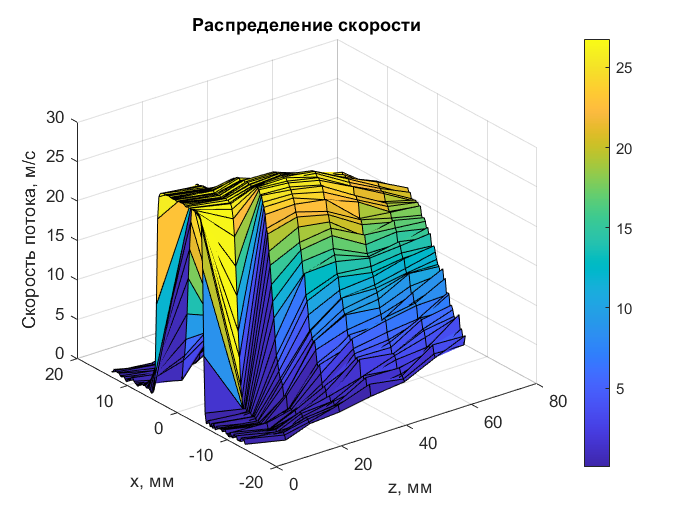


surf(z, xvCentered, v)
title('Распределение скорости')
colorbar

xlabel('z, мм')
zlabel('Скорость потока, м/с')
ylabel('x, мм')

saveas(f4, 'Скорость.png')



Q = zeros(8)

Q = 8×8
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0



for i = 1:size(v,1)
    y0 = v(i,:).*abs(xvCentered(i,:))
    x0 = xvCentered(i,:).*10^(-3)
    Q(i) = 2*1.2*pi*trapz(x0,y0)
end

y0 = 1×108
    4.4067   11.7890    9.8566   10.9163    4.0677    4.6328    3.7813    9.2254    7.0339    9.0773    3.0521    4.2130    7.9703    1.5001    3.3593    3.4428    7.4908    6.7862    3.3872    4.4989    4.6735    3.6320    3.5950    4.6549    0.8143    5.4227    0.8445    4.0128    0.9231    4.8667


x0 = 1×108
   -0.0130   -0.0128   -0.0125   -0.0123   -0.0120   -0.0118   -0.0115   -0.0112   -0.0110   -0.0108   -0.0105   -0.0103   -0.0100   -0.0097   -0.0095   -0.0092   -0.0090   -0.0088   -0.0085   -0.0083   -0.0080   -0.0077   -0.0075   -0.0073   -0.0070   -0.0067   -0.0065   -0.0063   -0.0060   -0.0057


Q = 8×8
    5.0679         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
    1.7014    9.7451   12.7730   10.0092   10.3874   11.4794    4.3156    7.2564    9.4557    9.0421    9.1897    7.9906    6.2666    5.0360    2.5872   11.0223    7.0422    7.9097    4.7087    2.6928    4.8129    5.2838    6.1860    3.4992    6.7638    8.0587    7.2865    6.0037    8.9969    9.0131


x0 = 1×108
   -0.0146   -0.0144   -0.0141   -0.0139   -0.0136   -0.0134   -0.0131   -0.0129   -0.0126   -0.0124   -0.0121   -0.0119   -0.0116   -0.0114   -0.0111   -0.0109   -0.0106   -0.0104   -0.0101   -0.0099   -0.0096   -0.0094   -0.0091   -0.0089   -0.0086   -0.0084   -0.0081   -0.0079   -0.0076   -0.0074


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
    4.4067    5.3448    9.0173   10.8464    8.4863    0.9647    8.2960   11.5143   12.5954    8.6137    7.5250    4.9853    9.8308    9.1740    6.1496    7.7550    8.4683    7.2292    3.9530   18.3620   17.9146   14.4444   24.2897   27.6680   27.8429   32.6689   38.0181   41.5450   52.3124   64.6197


x0 = 1×108
   -0.0130   -0.0128   -0.0125   -0.0123   -0.0120   -0.0118   -0.0115   -0.0112   -0.0110   -0.0108   -0.0105   -0.0103   -0.0100   -0.0097   -0.0095   -0.0092   -0.0090   -0.0088   -0.0085   -0.0083   -0.0080   -0.0077   -0.0075   -0.0073   -0.0070   -0.0067   -0.0065   -0.0063   -0.0060   -0.0057


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
    3.3745   12.8813    9.6642   10.1590    8.9695   13.1266   12.0610   10.1112   16.8004   12.3458   11.2779   19.1051   23.7046   12.4172   23.7876   33.4156   41.0391   36.2417   38.6542   49.6629   55.8969   52.4453   53.2443   57.1343   54.2617   63.9478   71.0924   71.8363   82.9728   77.8276


x0 = 1×108
   -0.0124   -0.0121   -0.0119   -0.0116   -0.0114   -0.0111   -0.0109   -0.0106   -0.0104   -0.0101   -0.0099   -0.0096   -0.0094   -0.0091   -0.0089   -0.0086   -0.0084   -0.0081   -0.0079   -0.0076   -0.0074   -0.0071   -0.0069   -0.0066   -0.0064   -0.0061   -0.0059   -0.0056   -0.0054   -0.0051


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
    8.7998         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
   10.2623   27.3865    5.6540   16.4644   32.0881   17.8803   31.2744   25.4305   25.8835   47.0218   34.8960   45.5107   37.9550   45.6743   49.1447   57.4924   48.3878   56.6827   50.8358   56.4368   67.5730   65.0107   66.5520   72.3987   68.5905   71.4263   77.2701   75.6579   79.6536   79.5588


x0 = 1×108
   -0.0121   -0.0119   -0.0116   -0.0114   -0.0111   -0.0109   -0.0106   -0.0104   -0.0101   -0.0099   -0.0096   -0.0094   -0.0091   -0.0089   -0.0086   -0.0084   -0.0081   -0.0079   -0.0076   -0.0074   -0.0071   -0.0069   -0.0066   -0.0064   -0.0061   -0.0059   -0.0056   -0.0054   -0.0051   -0.0049


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
    8.7998         0         0         0         0         0         0         0
    9.6305         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
   18.2552   21.0977   24.8122   25.4467   33.0085   17.8750   28.1011   38.6994   42.5174   43.3307   39.7537   47.0248   50.8197   51.6843   58.1349   68.2603   68.6219   59.8396   60.6478   63.7560   67.2514   72.1833   74.9586   75.2142   74.5740   77.5823   76.9401   77.4816   79.2722   76.0452


x0 = 1×108
   -0.0124   -0.0121   -0.0119   -0.0116   -0.0114   -0.0111   -0.0109   -0.0106   -0.0104   -0.0101   -0.0099   -0.0096   -0.0094   -0.0091   -0.0089   -0.0086   -0.0084   -0.0081   -0.0079   -0.0076   -0.0074   -0.0071   -0.0069   -0.0066   -0.0064   -0.0061   -0.0059   -0.0056   -0.0054   -0.0051


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
    8.7998         0         0         0         0         0         0         0
    9.6305         0         0         0         0         0         0         0
   10.1802         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
   37.0562   40.7877   52.1255   36.2227   39.1987   44.6616   34.9458   38.7337   49.5574   56.1587   55.4330   64.3134   63.8868   57.9356   57.6306   69.2315   69.0487   67.3626   73.5495   67.9086   73.0016   80.6277   77.1767   73.8822   73.9546   77.4619   73.9407   73.6977   74.2417   72.6825


x0 = 1×108
   -0.0120   -0.0118   -0.0115   -0.0112   -0.0110   -0.0108   -0.0105   -0.0103   -0.0100   -0.0097   -0.0095   -0.0092   -0.0090   -0.0088   -0.0085   -0.0083   -0.0080   -0.0077   -0.0075   -0.0073   -0.0070   -0.0067   -0.0065   -0.0063   -0.0060   -0.0057   -0.0055   -0.0053   -0.0050   -0.0047


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
    8.7998         0         0         0         0         0         0         0
    9.6305         0         0         0         0         0         0         0
   10.1802         0         0         0         0         0         0         0
   10.8061         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


y0 = 1×108
   50.5057   35.0343   45.1059   53.8864   47.8972   68.1181   52.7480   55.2940   56.2034   55.9935   61.2758   63.9591   56.0325   70.2603   69.2270   63.9309   77.1147   69.7816   79.3152   71.5205   67.8567   70.9568   69.1554   69.4496   71.0301   71.5782   66.1892   63.8901   67.2890   60.7820


x0 = 1×108
   -0.0115   -0.0112   -0.0110   -0.0108   -0.0105   -0.0103   -0.0100   -0.0097   -0.0095   -0.0092   -0.0090   -0.0088   -0.0085   -0.0083   -0.0080   -0.0077   -0.0075   -0.0073   -0.0070   -0.0067   -0.0065   -0.0063   -0.0060   -0.0057   -0.0055   -0.0053   -0.0050   -0.0047   -0.0045   -0.0043


Q = 8×8
    5.0679         0         0         0         0         0         0         0
    5.7255         0         0         0         0         0         0         0
    7.2713         0         0         0         0         0         0         0
    8.7998         0         0         0         0         0         0         0
    9.6305         0         0         0         0         0         0         0
   10.1802         0         0         0         0         0         0         0
   10.8061         0         0         0         0         0         0         0
   10.9872         0         0         0         0         0         0         0



Q = Q(:,1)'/2

Q = 1×8
    2.5339    2.8627    3.6357    4.3999    4.8153    5.0901    5.4030    5.4936



hold off


f5 = figure

f5 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


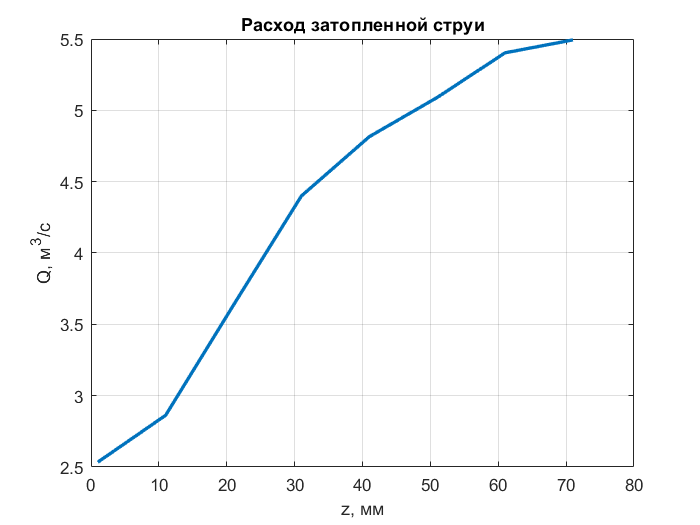

figure(f5)
plot(z(:,1)', Q, 'LineWidth',2)
grid on
title('Расход затопленной струи')
ylabel('Q, м^3/c')
xlabel('z, мм')

saveas(f5, 'Струя.png')